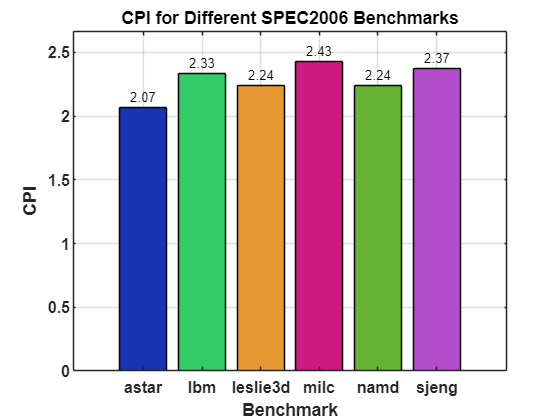

% Benchmark names (from file names)
benchmarks = {'astar', 'lbm', 'leslie3d', 'milc', 'namd', 'sjeng'};

% Number of CPU cycles (from your stats.txt files)
num_cycles = [20661341, 23332898, 22416617, 24260916, 22384585, 23717350];

% Number of instructions (from your stats.txt files)
num_instructions = [10000000, 10000001, 10000001, 10000000, 10000000, 10000000];

% Calculate CPI
cpi = num_cycles ./ num_instructions;

% Create bar chart
figure;
b = bar(cpi, 'FaceColor', 'flat');

% Setting a different color for each bar (it was ugly before!)
colors = [
    0.1 0.2 0.7;  % Color for astar (RGB)
    0.2 0.8 0.4;  % Color for lbm (RGB)
    0.9 0.6 0.2;  % Color for leslie3d (RGB)
    0.8 0.1 0.5;  % Color for milc (RGB)
    0.4 0.7 0.2;  % Color for namd (RGB)
    0.7 0.3 0.8;  % Color for sjeng (RGB)
];

% Apply the colors to the bars
b.CData = colors;

% Set X-axis labels to benchmark names
set(gca, 'XTickLabel', benchmarks);

% Add grid lines
grid on;

% Labeling axes
xlabel('Benchmark');
ylabel('CPI');
title('CPI for Different SPEC2006 Benchmarks');

% Display values on top of the bars
for i = 1:length(cpi)
    text(i, cpi(i) + 0.02, num2str(cpi(i), '%.2f'), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

% Set Y-axis limit to a higher value
ylim([0 max(cpi) * 1.1]);  % Increase the upper limit by 10%

% Customize the appearance
set(gca, 'FontSize', 12, 'FontWeight', 'bold');